# Introduction to MATLAB

## Scalar

 A scalar is a single number. MATLAB works with IEEE double‑precision by default.

### Variable Assignment:

Lines ending with a semicolon `;` suppress command‑window. Omit it to display results.

a = 1

a = 1

b = a + 2;
c = a + b;
c = c + 1;

Note that only the first line is displayed. However, the  variables are computed and store in the workspace.

### Pre-defined Constant:

MATLAB provides handy constants like `pi`, `eps`, `realmax`, and `realmin`. 

pi 

ans = 3.1416

i

ans = 0.0000 + 1.0000i

j

ans = 0.0000 + 1.0000i

eps       % floating-point relative accuracy

ans = 2.2204e-16

realmax   % Largest Floating-point number

ans = 1.7977e+308

realmin   % Smallest Floating-point number

ans = 2.2251e-308

Be aware that these are *numeric approximations* (e.g., `pi` ≈ 3.14159265…). You can override these names (try not to!), and restore the defaults by `clear pi`, `clear eps`, etc.

pi = 3;
2*pi

ans = 6

clear pi
pi

ans = 3.1416

### Baisc Arithmetics, Inf, and NaN:

MATLAB has a rich set of built‑ins: `sin`, `cos`, `exp`, `log`, `log10`, `log2`, etc.

% Division by zero yields `Inf`; 0/0 yields `NaN`. MATLAB will not error by default— it's up to you to check for them when it matters (e.g., input validation).

a = 1 + 2 - 3*(4/5^6)

a = 2.9992

b = sin(pi/2) + cos(pi) + exp(a) - log(exp(1)) + log10(10) - log2(2)

b = 19.0701


cInf = 1/0   % Infinity

cInf = Inf

cNaN = 0/0   % Not-a-number

cNaN = NaN

### Floating-point vs. symbolic math:

Floating‑point arithmetic is approximate. For example, `cos(pi/2)` won’t print exactly zero because `pi` is a rounded double. If you need exact arithmetic (algebraic manipulation, proofs), use **Symbolic Math Toolbox** and its exact constants.

cos(pi/2)

ans = 6.1232e-17


cos(sym(pi)/2)

$$ans = 0$$

### Boolean & Logical Operations:

A boolean (logical) represents truth and takes exactly two values: `true` or `false`. Comparisons produce logical results, and logical operators let you combine or negate them.

true

ans = logical
   1


false

ans = logical
   0


a = 3<1

a = logical
   0


b = pi<=3

b = logical
   0


c = a & b

c = logical
   0


d = ~c | false

d = logical
   1


## Vector

### Row vs. Column, Sizes and Shapes:

Vectors are 1×N (row) or N×1 (column) arrays. MATLAB is **1‑indexed** (first element is index 1). Use `numel` for number of elements, and `size(x,dim)` for a specific dimension.

v_col = [1.2; -2; pi];              
v_row = [1.2, -2, pi];              

numel(v_col)

ans = 3

[r, c] = size(v_row)                

r = 1

c = 3

size(v_col, 1)           

ans = 3

size(v_row, 2)         

ans = 3

### Creating vectors: colon notation and linspace:

 The **colon operator, : ,** creates arithmetic progressions: 'start:step:end' generates values 'start, start+step, ...' up to the last value that does **not exceed** 'end' in the sign of 'step'.

seq1 = 1:10

seq1 =      1     2     3     4     5     6     7     8     9    10


seq1b = 1:10.1

seq1b =      1     2     3     4     5     6     7     8     9    10


'10.1' is past the next step after 10, so the last value included is still 10.

The step can be customed. 

seq2 = 1:2:10

seq2 =      1     3     5     7     9


seq3 = 1:0.5:10;

If you write `10:1` MATLAB interprets it as start=10, step=1, end=1, which returns an empty vector because 'start' is greater than 'end' for a positive step. To count down, use a **negative step**.

decEmpty = 10:1 


decEmpty =

  1×0 empty double row vector



decSeq = 10:-1:1

decSeq =     10     9     8     7     6     5     4     3     2     1


'linspace(a,b,N)' returns N **evenly spaced** points from a to b including both endpoints.

grid10 = linspace(1, 19, 10)

grid10 =      1     3     5     7     9    11    13    15    17    19


### Accessing, assigning, deleting, concatenating:

Use parentheses to index. 

v = (0:2:20)';                      % column vector of even numbers
v(3)                                % 3rd element
v([1 3 5])                          % 1st, 3rd, 5th

'end' refers to the last index along a dimension.

v(end)                              % last
v(end-1)                            % second‑to‑last
v(1:2:end)                          % every other element
v(end-4:end)                        % last 5 elements

You can assign into indices, delete elements by assigning `[]`, and grow arrays by assigning past the end. 


v(1) = 420;                         % replace first
v([1 3 5]) = 0;                     % bulk assign
v([2 4]) = [];                      % delete elements
v(end+1) = 3.14;                    % append

Concatenate with `[]` horizontally or vertically.

vA = [1 2 3 4];  vB = [5 6 7 8];
hcat = [vA vB]                       % horizontal concat (row)
vA = vA.';  vB = vB.';
vcat = [vA; vB]                      % vertical concat (column)

### Vectorization & element‑wise ops:

Many MATLAB functions accept entire vectors/matrices and operate element‑wise (vectorization). For operators, use the dotted forms `.*`, `./`, `.^` to request element‑wise behavior. This is faster and more compact than writing explicit loops in many cases.

Example:


$$\begin{array}{l}
y_1 \left(t\right)=\sin \left(t\right)\\
y_2 \left(t\right)=t^2 
\end{array}$$


t = 0:0.1:10;
y1 = sin(t)                         % vectorized sine

y1 =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508   -0.4425   -0.5298   -0.6119   -0.6878   -0.7568   -0.8183   -0.8716   -0.9162   -0.9516   -0.9775   -0.9937   -0.9999   -0.9962   -0.9825


try
    yerror = t^2
catch exception
    disp(exception.message)
end

Incorrect dimensions for raising a matrix to a power. Check that the matrix is square and the power is a scalar. To operate on each element of the matrix individually, use POWER (.^) for elementwise power.


y2 = t.^2

y2 =          0    0.0100    0.0400    0.0900    0.1600    0.2500    0.3600    0.4900    0.6400    0.8100    1.0000    1.2100    1.4400    1.6900    1.9600    2.2500    2.5600    2.8900    3.2400    3.6100    4.0000    4.4100    4.8400    5.2900    5.7600    6.2500    6.7600    7.2900    7.8400    8.4100    9.0000    9.6100   10.2400   10.8900   11.5600   12.2500   12.9600   13.6900   14.4400   15.2100   16.0000   16.8100   17.6400   18.4900   19.3600   20.2500   21.1600   22.0900   23.0400   24.0100


## Matrices

### Construction:

Create matrices by rows or by concatenating column vectors. MATLAB stores arrays in **column‑major** order.

Example:


$$\mathbf{A}=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
2 & 4 & 6 & 8\\
3 & 6 & 9 & 12
\end{array}\right\rbrack$$


A = [1 2 3 4; 2 4 6 8; 3 6 9 12]

A =      1     2     3     4
     2     4     6     8
     3     6     9    12


A = [[1;2;3] [2;4;6] [3;6;9] [4;8;12]]

A =      1     2     3     4
     2     4     6     8
     3     6     9    12


 Useful constructors include 'zeros', 'ones', and 'eye' (identity).

Z3  = zeros(3);       % 3×3 zero matrix
Z35 = zeros(3,5);     % 3-by-5 zero matrix
O26 = ones(2,6);      % 2-by-6 one matrix
I4  = eye(4);         % 4-by-4 identity matrix

### Matrix indexing:

Index with (row, col). Multiple rows and columns can be accessed with vector of indices.

A(3,4)                % row 3, col 4

ans = 12

A([1 3], :)           % rows 1 and 3, all columns

ans =      1     2     3     4
     3     6     9    12



A(1,1:end-1)          % first row, excluding last column

ans =      1     2     3


ans = 3

A single index uses linear (column‑major) indexing. This means elements are counted down columns first, then across.

A(7)

### Matrix multiplication: dimensions & order matter:

For 'A*B' to be valid, 'size(A,2) == size(B,1)'. Matrix multiplication is not commutative: generally 'A*B ~= B*A'. %

Example:


$$\mathbf{A}=\left\lbrack \begin{array}{cccc}
1 & 2 & 3 & 4\\
2 & 4 & 6 & 8\\
3 & 6 & 9 & 12
\end{array}\right\rbrack ,\;\;\mathbf{B}=\left\lbrack \begin{array}{cc}
1 & 5\\
2 & 6\\
3 & 7\\
4 & 8
\end{array}\right\rbrack ,\;\mathbf{c}=\left\lbrack \begin{array}{c}
1\\
-1
\end{array}\right\rbrack \;$$
  

A = [1:1:4; 2:2:8; 3:3:12];
B = [1 5; 2 6; 3 7; 4 8];
c = [1; -1];

result = A * B * c

result =    -40
   -80
  -120


### Solving linear systems:

To solve 'A*x = b', use 'x = A\b'. It’s faster and numerically more stable than 'inv(A)*b'. MATLAB chooses a suitable factorization under the hood (LU/QR/Cholesky/etc.).

Example:


$$\begin{array}{l}
2x+y-z=1\\
x+z=2\\
2y+2z=1
\end{array}$$


This can be rewritten as:


$$\left\lbrack \begin{array}{ccc}
2 & 1 & -1\\
1 & 0 & 1\\
0 & 2 & 2
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
1\\
2\\
1
\end{array}\right\rbrack \Rightarrow \left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack ={\left\lbrack \begin{array}{ccc}
2 & 1 & -1\\
1 & 0 & 1\\
0 & 2 & 2
\end{array}\right\rbrack }^{-1} \left\lbrack \begin{array}{c}
1\\
2\\
1
\end{array}\right\rbrack$$


result = [2 1 -1; 1 0 1; 0 2 2]\[1;2;1]

result =     1.1250
   -0.3750
    0.8750


### Some helpful operations:

'[V,D] = eig(A)' gives eigenvectors (columns of V) and eigenvalues (diag of D).

'[U,S,V] = svd(A)' gives the singular value decomposition.

'reshape', 'repmat', and 'permute' help reorganize data/tensors.

A = magic(4);                   % "magic square" matrix
[V,D] = eig(A);                 
[U,S,VT] = svd(A);              
A_sq = A.^2;                    
B = reshape(A, [2,8]);          
C = repmat(A, [2,3]);           
T = rand(2,3,4);                
Tp = permute(T, [1 3 2]); 

## Visualization

### Example 1: Single Plot

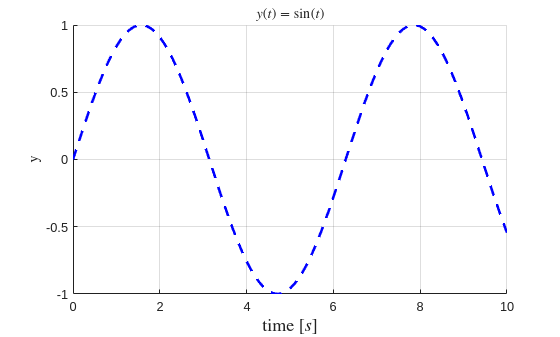

% Data
t = (0:0.1:10)';
y = sin(t);
hold('on');         % hold axis for multiple plots
% plot with dotted line and corresponding colors in 'c'
plot(t,y,'b--','LineWidth',2);
grid('on');          % add grid for readability
xticks(0:2:t(end));  % assign ticks on horizontal axis
xticklabels(0:2:t(end)); % assign tick labels on horizontal axis
% add label for horizontal axis
xlabel('time [$s$]','FontSize',14, 'Interpreter','latex')
% add label for vertical axis
ylabel('y','Interpreter','latex')
% add title to the plot
title('$y(t)=\sin(t)$','Interpreter','latex')

### Example 2: Axis Manipulation

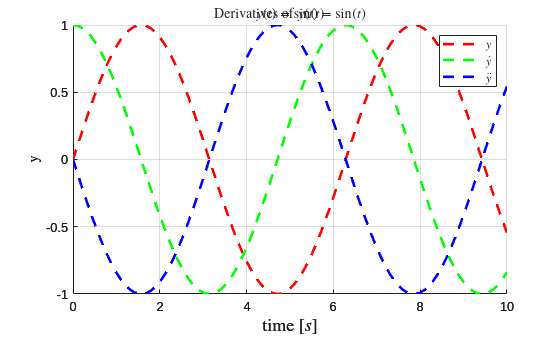

% Data
t = (0:0.1:10)';
y = [sin(t) cos(t) -sin(t)];
ax = axes;             % create axis for handling plot consistently
hold(ax,'on');         % hold axis for multiple plots
c = 'rgbmkyc';         % array of colors (char)
% loop over all channels in y
for i = 1:size(y,2)
   % plot with dotted line and corresponding colors in 'c'
   % Line's width is 2.
   plot(ax,t,y(:,i),[c(i) '--'],'LineWidth',2);
end
grid(ax,'on');          % add grid for readability
xticks(ax,0:2:t(end));  % assign ticks on horizontal axis
xticklabels(ax,0:2:t(end)); % assign tick labels on horizontal axis
% add label for horizontal axis
xlabel(ax,'time [$s$]','FontSize',14, 'Interpreter','latex')
% add label for vertical axis
ylabel(ax,'y','Interpreter','latex')
% add legends to the plot using latex interpreter
legend('$$y$$','$$\dot{y}$$','$$\ddot{y}$$','interpreter','latex')
% add title to the plot
title('Derivatives of $y(t)=\sin(t)$','Interpreter','latex')

### Example 3: Subplots

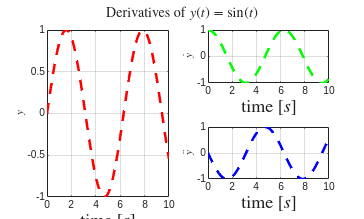

% Data
t = (0:0.1:10)';
y = [sin(t) cos(t) -sin(t)];
ax_1 = subplot(2,2,[1 3]);
ax_2 = subplot(2,2,2);
ax_3 = subplot(2,2,4);
ax = [ax_1;ax_2;ax_3];
c = 'rgbmkyc';         % array of colors (char)
% cell array of strings
ylabels = {'$$y$$','$$\dot{y}$$','$$\ddot{y}$$'};
% loop over all channels in y
for i = 1:size(y,2)
   % plot with dotted line and corresponding colors in 'c'
   % Line's width is 2.
   plot(ax(i),t,y(:,i),[c(i) '--'],'LineWidth',2);
   grid(ax(i),'on');         
   xticks(ax(i),0:2:t(end)); 
   xticklabels(ax(i),0:2:t(end));
   xlabel(ax(i),'time [$s$]','FontSize',14, 'Interpreter','latex')
   ylabel(ax(i),ylabels{i},'Interpreter','latex')
end
% add title to the figure
sgtitle('Derivatives of $y(t)=\sin(t)$','Interpreter','latex')

### Example 4: Animation

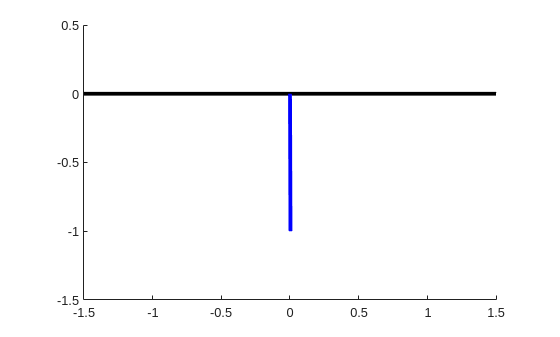

clf;
m = 1;
l = 1;
b = 1;
g = 9.80665;
t_max = 10;
x_0 = [pi/2;0];
[t,x] = ode45(@(t,x)[x(2);(g/l)*sin(x(1))-(b/(m*l^2))*x(2)],[0 t_max],x_0);
ax = axes;
hold(ax,'on')
axis(ax,'equal')  % make sure that axis are in the same scale
axis(ax,[-1.5,1.5,-1.5,0.5])
% Static plot for ground
plot(ax,[-2 2],[0 0],'k','LineWidth',3)
% Initial plot to instantiate plot handle
theta = x(1,1);
h_pendulum = plot(ax,[0 l*sin(theta)],[0 l*cos(theta)],'b','LineWidth',3);
% Loop over the remaining time stamp
for i = 2:numel(t)
   pause(t(i)-t(i-1));
   theta = x(i,1);
   % Instead of replotting, change the data.
   h_pendulum.XData = [0 l*sin(theta)];
   h_pendulum.YData = [0 l*cos(theta)];
end